clc
clear

% %frecuencias admitidas (8000, 11025, 22050 y 44100), el tipo
% Fs = 44100;
% 
% recObj = audiorecorder(44100, 16, 1);
% 
% disp('Start speaking.')
% recordblocking(recObj, 3);
% disp('End of Recording.');
% 
% play(recObj);
% 
% y = getaudiodata(recObj);
% plot(y);
% TL = 80e-3 ;
% L = TL*Fs; 
% NFFT = 2^nextpow2(L);
% overlap= floor(0.7*L);
% figure
% pwelch(y,hamming(L),overlap, NFFT, Fs)
% [pxx,f] =pwelch(y,hamming(L),overlap, NFFT, Fs);
% 
% [pks,locs] = findpeaks(10*log10(pxx),"NPeaks",2)
% sort(f(locs))
% 
% figure
% specgram(y,NFFT,Fs,hamming(L),overlap); colorbar;
% 
% 
% %Oli ya llegie
% %hola

% switch mode
%     case 'Primera'
%         x = -5;
%     case 'Segunda'
%         x = -10;
%     case 'Tercera'
%         x = -14;
%     case 'Cuarta'
%         x = -19;
%     case 'Quinta'
%         x = -24;
%     case 'Sexta'
%         x = -29;
% end


Proyecto 1

## Afinador de instrumentos musicales

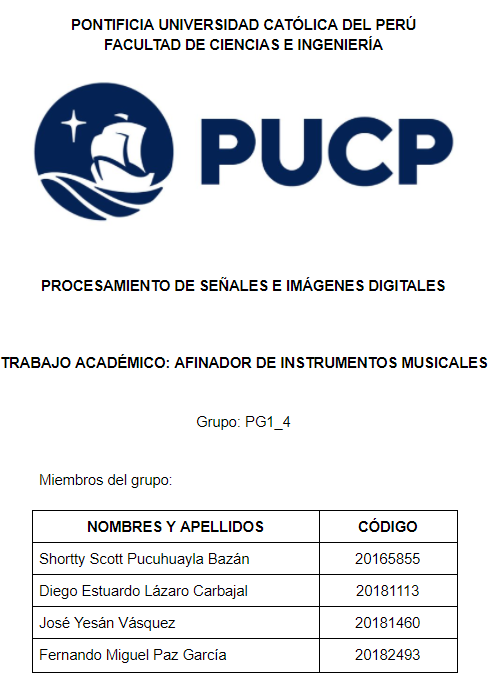

Ingrese la cuerda a afinar...

prompt='ingrese el número de cuerda: ';
mode = input(prompt);

switch mode
    case 1
        x = -5;
    case 2
        x = -10;
    case 3
        x = -14;
    case 4
        x = -19;
    case 5
        x = -24;
    case 6
        x = -29;
end

Grabaciónde la nota

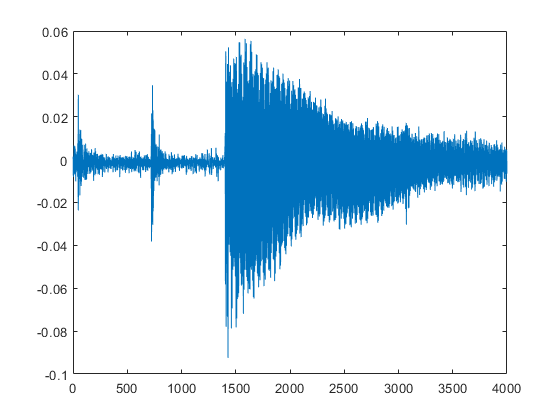

fs = 2000;
recObj = audiorecorder(fs, 16, 1);
recordblocking(recObj, 2);
y = getaudiodata(recObj);

plot(y)

Filtraje de sonido

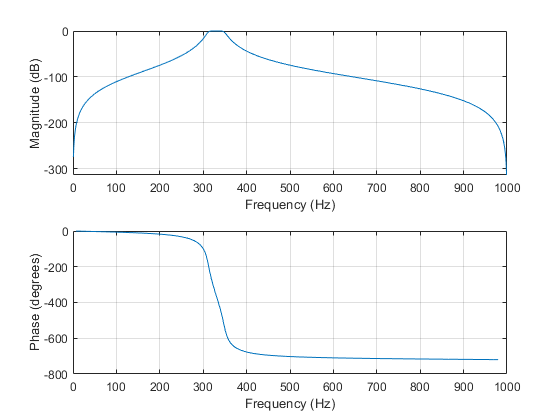

F1 = 440*2^((x-1)/12);
F2 = 440*2^((x+1)/12);
wp1 = F1/(fs/2);
wp2 = F2/(fs/2);
Wp= [wp1 wp2];
[b, a] = butter(4,Wp,'bandpass');
freqz(b,a,1024,fs)

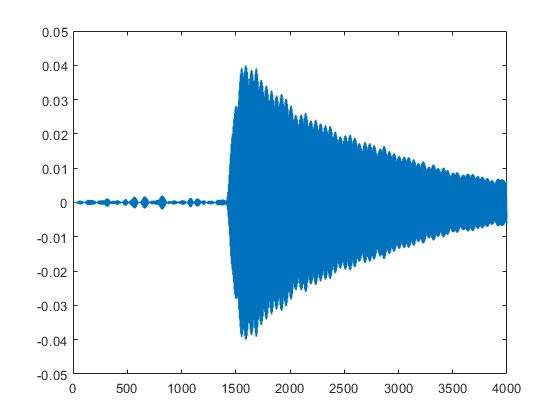

y1= filter(b,a,y);

plot(y1)

Análisis por periodograma de Welch

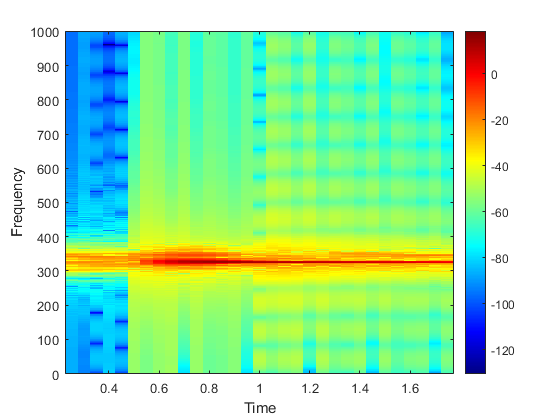

L = 0.5*fs;
overlap = floor(0.9*L);
nfft = 2^nextpow2(L);
[pxx,f] = pwelch(y1,hamming(L),overlap,nfft,fs);
[pks, locs] = findpeaks(pxx,'SortStr','descend','NPeaks',1);
pk= f(locs);

figure
specgram(y1,nfft,fs,hamming(L),overlap); colorbar;

Respuesta al usuario

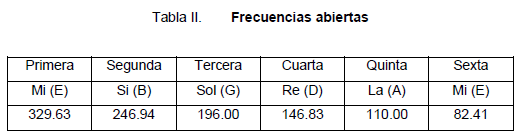

pk1 = string(pk);
disp("Frecuencia Actual: " + pk1);

Frecuencia Actual: 326.1719


order1 = 12 * log2(pk/440);

n = x - order1;
if n< - 0.35 
    disp("Estado: Por encima de la frecuencia");
elseif n > 0.35
    disp("Estado: Por debajo de la frecuencia");
else
    disp("Estado: En rango");
end

Estado: En rango
